# A robotic test of proprioception within the hemiparetic arm post-stroke - Simo et al

clear; clc; cd('/Users/duncan/Dropbox/BIOMS/Qualifying/Exam/Simo/Code')


## Recreate a psychometric function + fit a curve 

% randomly pick which distribution to chose from, end after 60 correct
% answers 
clear n refsp testsp sp correct wrong
resp = [1,2];
done = 0;
i = 1;
while done == 0
    b = datasample(resp,1);
    [ref_dur, ~, done, right] = stepping(b);
    if ~isempty(ref_dur) 
        dur_ans(i,1) = ref_dur;
        dur_ans(i,2) = right;
        i = i+1;
    else
        return
    end
end

ans = 'Correct: 1; Wrong: 0; n: 4; test_dur: 4.310000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 1; Wrong: 1; n: 5; test_dur: 8.720000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 1; Wrong: 2; n: 5; test_dur: 3.860000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 1; Wrong: 3; n: 5; test_dur: 6.570000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 2; Wrong: 3; n: 4; test_dur: 1.136000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 3; Wrong: 3; n: 3; test_dur: 4.210000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 4; Wrong: 3; n: 2; test_dur: 3.260000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 5; Wrong: 3; n: 1; test_dur: 4.620000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 5; Wrong: 4; n: 2; test_dur: 1.500000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 5; Wrong: 5; n: 3; test_dur: 4.210000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 6; Wrong: 5; n: 2; test_dur: 4.410000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 6; Wrong: 6; n: 3; test_dur: 1.209000e+00, ref_dur: 9.370000e-01'

ans = 'Correct: 6; Wrong: 7; n: 4; test_dur: 5.590000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 7; Wrong: 7; n: 3; test_dur: 7.350000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 8; Wrong: 7; n: 2; test_dur: 1.500000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 8; Wrong: 8; n: 3; test_dur: 1.209000e+00, ref_dur: 9.370000e-01'

ans = 'Correct: 8; Wrong: 9; n: 4; test_dur: 3.310000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 9; Wrong: 9; n: 3; test_dur: 4.120000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 10; Wrong: 9; n: 2; test_dur: 1.500000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 10; Wrong: 10; n: 3; test_dur: 4.120000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 10; Wrong: 11; n: 4; test_dur: 7.970000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 11; Wrong: 11; n: 3; test_dur: 5.430000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 11; Wrong: 12; n: 4; test_dur: 7.970000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 11; Wrong: 13; n: 5; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 12; Wrong: 13; n: 4; test_dur: 2.810000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 12; Wrong: 14; n: 5; test_dur: 4.870000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 13; Wrong: 14; n: 4; test_dur: 5.590000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 14; Wrong: 14; n: 3; test_dur: 3.440000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 15; Wrong: 14; n: 2; test_dur: 3.260000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 16; Wrong: 14; n: 1; test_dur: 1.785000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 17; Wrong: 14; n: 1; test_dur: 1.785000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 17; Wrong: 15; n: 2; test_dur: 6.810000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 18; Wrong: 15; n: 1; test_dur: 9.610000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 18; Wrong: 16; n: 2; test_dur: 3.570000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 19; Wrong: 16; n: 1; test_dur: 9.610000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 19; Wrong: 17; n: 2; test_dur: 4.410000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 19; Wrong: 18; n: 3; test_dur: 2.900000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 19; Wrong: 19; n: 4; test_dur: 2.810000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 19; Wrong: 20; n: 5; test_dur: 1.013000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 19; Wrong: 21; n: 5; test_dur: 3.200000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 19; Wrong: 22; n: 5; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 20; Wrong: 22; n: 4; test_dur: 2.810000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 21; Wrong: 22; n: 3; test_dur: 1.293000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 21; Wrong: 23; n: 4; test_dur: 3.310000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 21; Wrong: 24; n: 5; test_dur: 4.510000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 22; Wrong: 24; n: 4; test_dur: 2.810000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 23; Wrong: 24; n: 3; test_dur: 1.293000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 24; Wrong: 24; n: 2; test_dur: 3.940000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 24; Wrong: 25; n: 3; test_dur: 3.409000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 25; Wrong: 25; n: 2; test_dur: 2.500000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 25; Wrong: 26; n: 3; test_dur: 1.209000e+00, ref_dur: 9.370000e-01'

ans = 'Correct: 25; Wrong: 27; n: 4; test_dur: 5.590000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 26; Wrong: 27; n: 3; test_dur: 4.120000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 27; Wrong: 27; n: 2; test_dur: 5.000000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 27; Wrong: 28; n: 3; test_dur: 2.900000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 27; Wrong: 29; n: 4; test_dur: 7.070000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 28; Wrong: 29; n: 3; test_dur: 7.650000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 28; Wrong: 30; n: 4; test_dur: 3.500000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 28; Wrong: 31; n: 5; test_dur: 1.630000e+00, ref_dur: 9.370000e-01'

ans = 'Correct: 28; Wrong: 32; n: 5; test_dur: 1.630000e+00, ref_dur: 9.370000e-01'

ans = 'Correct: 29; Wrong: 32; n: 4; test_dur: 3.500000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 29; Wrong: 33; n: 5; test_dur: 3.860000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 29; Wrong: 34; n: 5; test_dur: 3.640000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 29; Wrong: 35; n: 5; test_dur: 1.630000e+00, ref_dur: 9.370000e-01'

ans = 'Correct: 30; Wrong: 35; n: 4; test_dur: 2.810000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 31; Wrong: 35; n: 3; test_dur: 4.120000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 31; Wrong: 36; n: 4; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 32; Wrong: 36; n: 3; test_dur: 4.120000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 33; Wrong: 36; n: 2; test_dur: 3.000000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 33; Wrong: 37; n: 3; test_dur: 1.293000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 33; Wrong: 38; n: 4; test_dur: 7.070000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 34; Wrong: 38; n: 3; test_dur: 4.210000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 35; Wrong: 38; n: 2; test_dur: 1.500000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 35; Wrong: 39; n: 3; test_dur: 7.350000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 35; Wrong: 40; n: 4; test_dur: 1.388000e+00, ref_dur: 9.370000e-01'

ans = 'Correct: 36; Wrong: 40; n: 3; test_dur: 3.440000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 37; Wrong: 40; n: 2; test_dur: 1.500000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 37; Wrong: 41; n: 3; test_dur: 2.900000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 37; Wrong: 42; n: 4; test_dur: 5.130000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 37; Wrong: 43; n: 5; test_dur: 3.860000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 37; Wrong: 44; n: 5; test_dur: 8.720000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 38; Wrong: 44; n: 4; test_dur: 1.136000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 39; Wrong: 44; n: 3; test_dur: 7.350000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 39; Wrong: 45; n: 4; test_dur: 3.500000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 39; Wrong: 46; n: 5; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 39; Wrong: 47; n: 5; test_dur: 1.013000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 40; Wrong: 47; n: 4; test_dur: 3.500000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 40; Wrong: 48; n: 5; test_dur: 3.860000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 41; Wrong: 48; n: 4; test_dur: 5.130000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 42; Wrong: 48; n: 3; test_dur: 2.900000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 42; Wrong: 49; n: 4; test_dur: 4.310000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 42; Wrong: 50; n: 5; test_dur: 6.570000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 42; Wrong: 51; n: 5; test_dur: 3.640000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 42; Wrong: 52; n: 5; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 43; Wrong: 52; n: 4; test_dur: 1.136000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 44; Wrong: 52; n: 3; test_dur: 1.293000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 44; Wrong: 53; n: 4; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 44; Wrong: 54; n: 5; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 44; Wrong: 55; n: 5; test_dur: 1.013000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 45; Wrong: 55; n: 4; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 45; Wrong: 56; n: 5; test_dur: 1.013000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 45; Wrong: 57; n: 5; test_dur: 3.200000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 45; Wrong: 58; n: 5; test_dur: 4.870000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 46; Wrong: 58; n: 4; test_dur: 4.030000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 47; Wrong: 58; n: 3; test_dur: 3.409000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 47; Wrong: 59; n: 4; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 47; Wrong: 60; n: 5; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 48; Wrong: 60; n: 4; test_dur: 3.500000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 49; Wrong: 60; n: 3; test_dur: 3.370000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 49; Wrong: 61; n: 4; test_dur: 5.130000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 49; Wrong: 62; n: 5; test_dur: 4.510000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 50; Wrong: 62; n: 4; test_dur: 4.030000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 51; Wrong: 62; n: 3; test_dur: 5.280000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 51; Wrong: 63; n: 4; test_dur: 3.310000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 51; Wrong: 64; n: 5; test_dur: 8.720000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 52; Wrong: 64; n: 4; test_dur: 1.388000e+00, ref_dur: 9.370000e-01'

ans = 'Correct: 52; Wrong: 65; n: 5; test_dur: 5.950000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 52; Wrong: 66; n: 5; test_dur: 6.570000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 52; Wrong: 67; n: 5; test_dur: 6.570000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 52; Wrong: 68; n: 5; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 53; Wrong: 68; n: 4; test_dur: 4.030000e-01, ref_dur: 4.680000e-01'

ans = 'Correct: 53; Wrong: 69; n: 5; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 53; Wrong: 70; n: 5; test_dur: 6.570000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 53; Wrong: 71; n: 5; test_dur: 8.720000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 54; Wrong: 71; n: 4; test_dur: 4.310000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 54; Wrong: 72; n: 5; test_dur: 4.510000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 55; Wrong: 72; n: 4; test_dur: 2.810000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 56; Wrong: 72; n: 3; test_dur: 5.430000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 56; Wrong: 73; n: 4; test_dur: 3.310000e-01, ref_dur: 3.740000e-01'

ans = 'Correct: 57; Wrong: 73; n: 3; test_dur: 5.430000e-01, ref_dur: 6.240000e-01'

ans = 'Correct: 58; Wrong: 73; n: 2; test_dur: 8.330000e-01, ref_dur: 9.370000e-01'

ans = 'Correct: 58; Wrong: 74; n: 3; test_dur: 1.293000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 58; Wrong: 75; n: 4; test_dur: 5, ref_dur: 1.874000e+00'

ans = 'Correct: 58; Wrong: 76; n: 5; test_dur: 3.640000e-01, ref_dur: 3.120000e-01'

ans = 'Correct: 59; Wrong: 76; n: 4; test_dur: 1.388000e+00, ref_dur: 9.370000e-01'

ans = 'Correct: 59; Wrong: 77; n: 5; test_dur: 1.013000e+00, ref_dur: 1.874000e+00'

ans = 'Correct: 60; Wrong: 77; n: 4; test_dur: 3.310000e-01, ref_dur: 3.740000e-01'

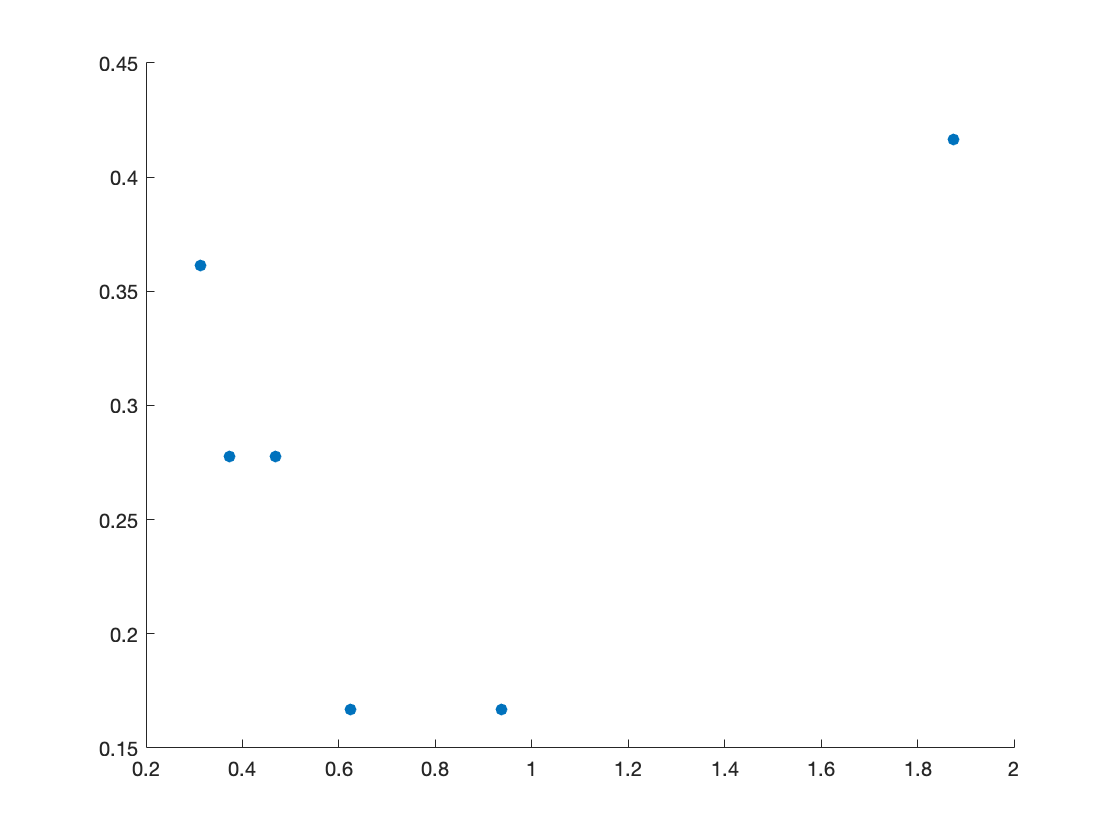

un = unique(dur_ans(:,1));

for refs = 1:length(un)
    ii = 1;
    for i = 1:length(dur_ans)
        if dur_ans(i,1) == un(refs)
            ref_per(ii,refs) = dur_ans(i,2);
            ii = ii+1;
        end
    end
end

sz = size(ref_per);
for refs = 1:length(un)
    ref_per(sz(1)+1,refs) = sum(ref_per(:,refs)/sz(1));
end

figure;
scatter(un,ref_per(end,:), 'filled')

% if data wasn't just randomly generated, I would be able to fit a line and get a psychometric function 


## Retry, fake data, cumulative Gaussian fit

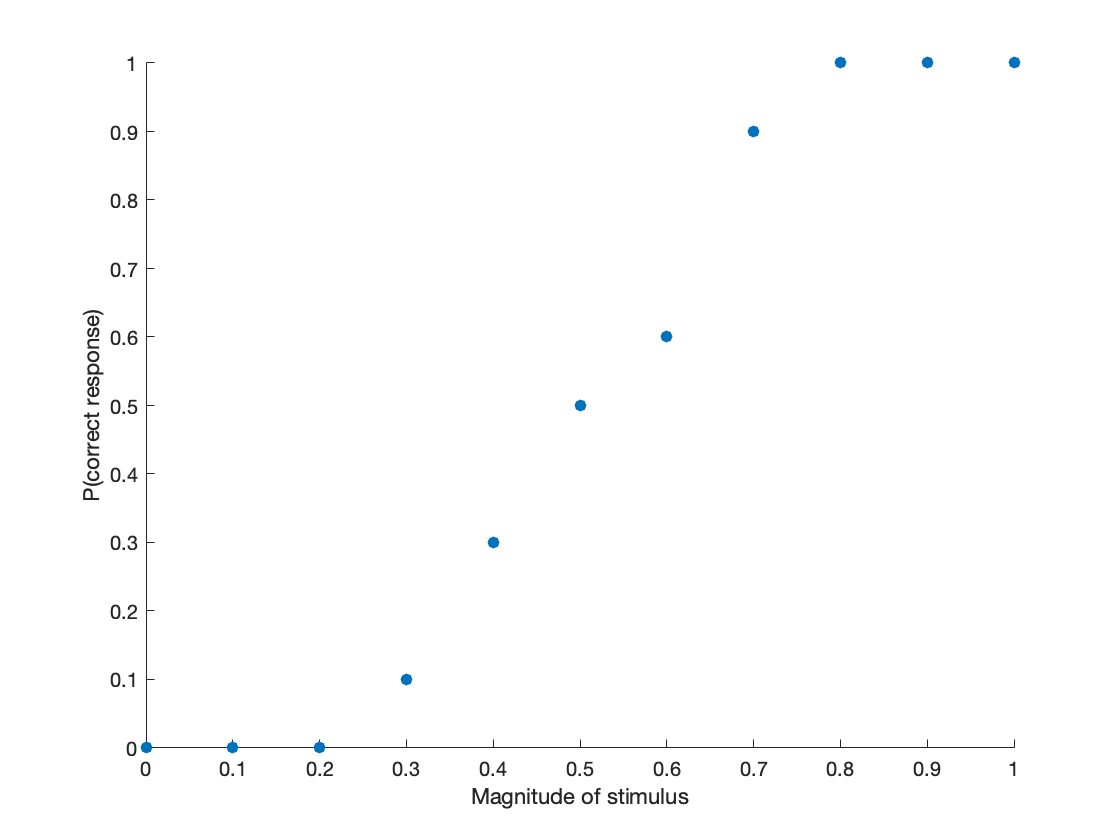

clear;clc;
% Create data
xdata = 0:0.1:1;
ydata = [0;0;0;0.1;0.3;0.5;0.6;0.9;1;1;1];

% Original plot 
figure;
scatter(xdata, ydata, 'filled')
xlabel('Magnitude of stimulus')
ylabel('P(correct response)')

% Try to fit data with lsqcurvefit
fun = @(b,xdata) (1 ./ (1 + exp(-b*(xdata - 0.5)))); 
b0 = 2;
% size(ydata)
% size(fun(x0,xdata))
b = lsqcurvefit(fun, b0, xdata, ydata')


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


b = 9.7087

times = linspace(xdata(1),xdata(end));
% Replot with fit line 
figure;
scatter(xdata, ydata, 'filled')
xlabel('Magnitude of stimulus')
ylabel('P(correct response)')
hold on 
plot(times, fun(b,times), 'b-')

mu = mean(ydata)

mu = 0.4909

sigma = std(ydata)

sigma = 0.4323

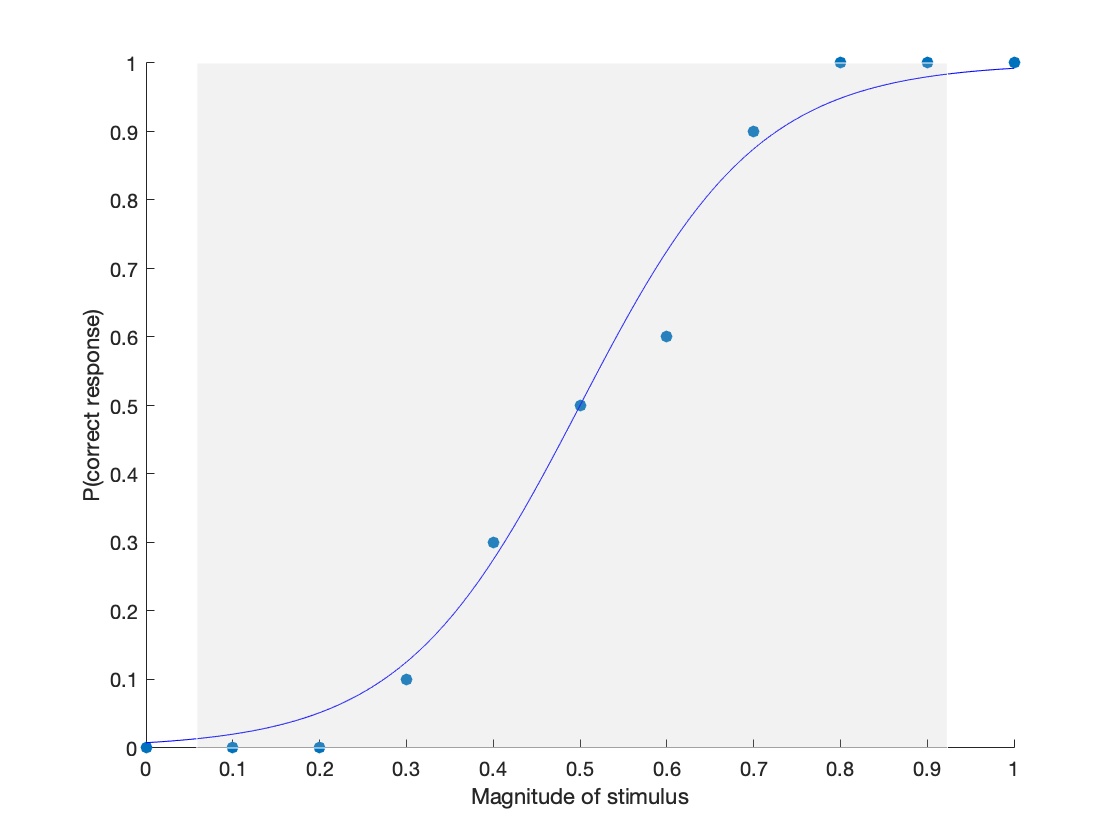

cornersx = [mu-sigma, mu+sigma, mu+sigma, mu-sigma];
cornersy = [0, 0, 1, 1];
p = patch(cornersx, cornersy, [.75 .75 .75], 'facealpha', .2);
p.EdgeColor = [1 1 1];

## Test out new function


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


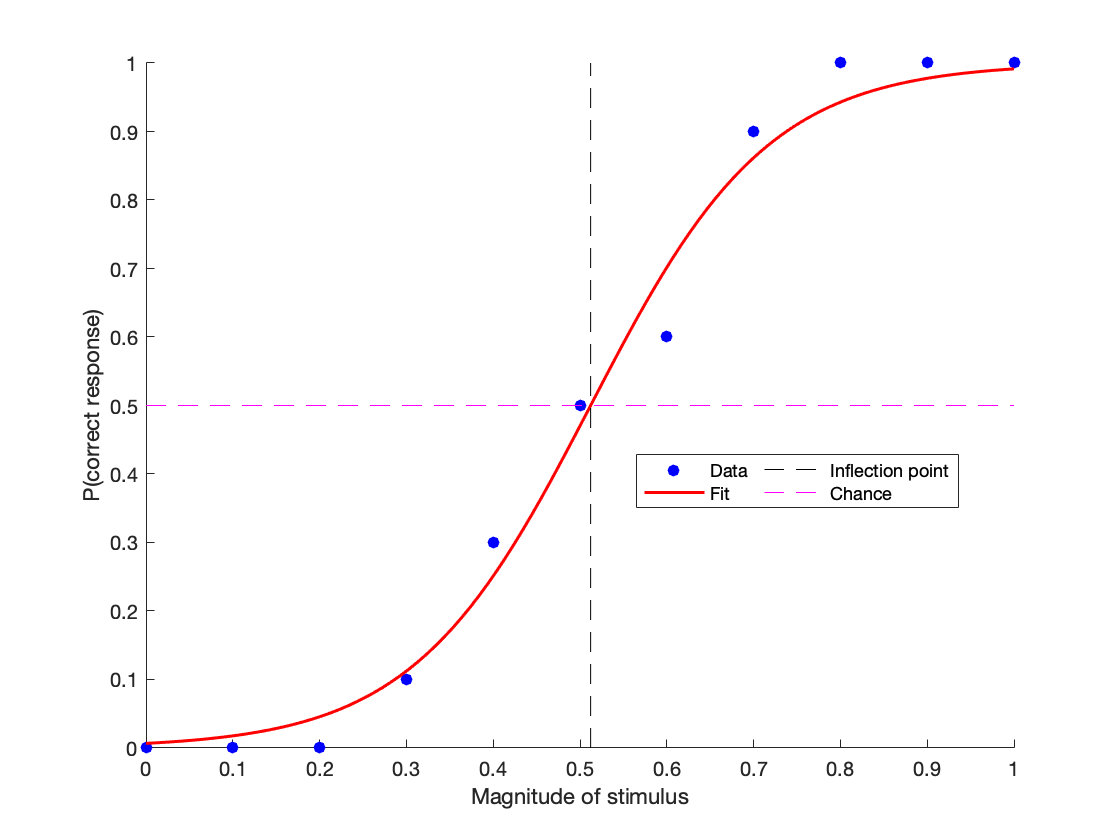

psychoparam =     9.7419    0.5122


data_stroke = [xdata',ydata];
psychoparam(1,:) = fit_psychometric(data_stroke, 'y')


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


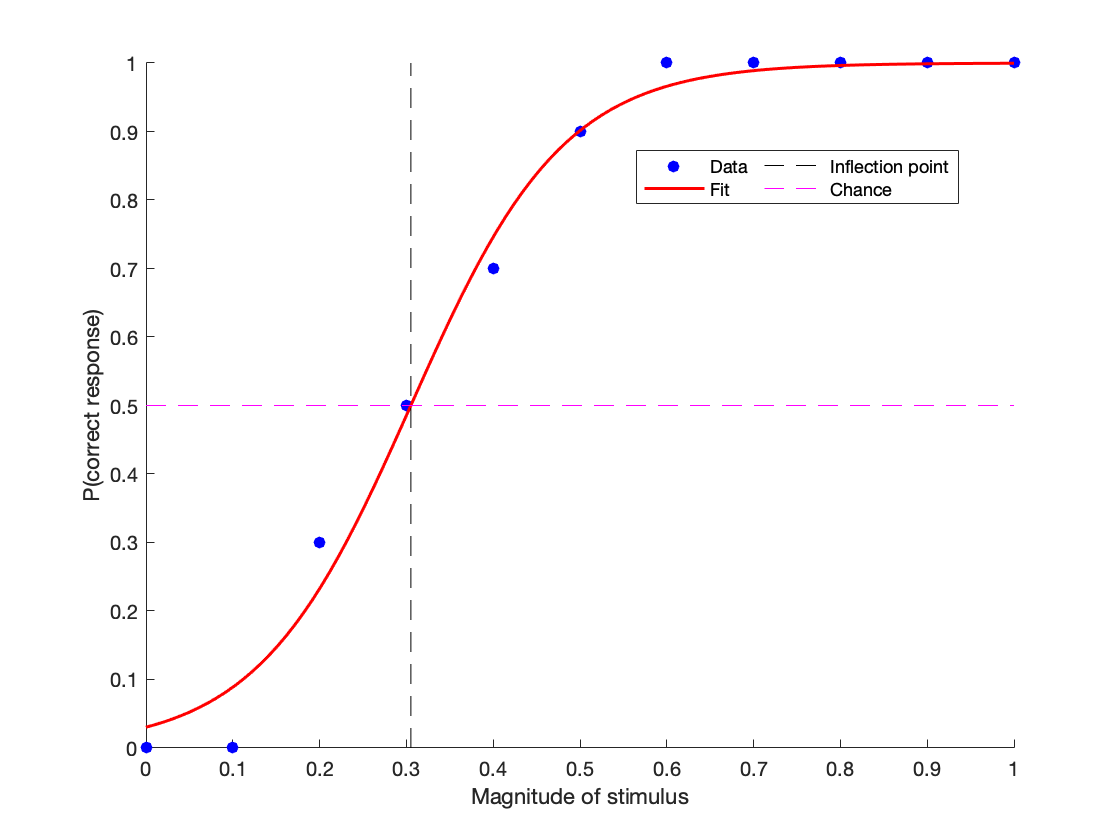

psychoparam =     9.7419    0.5122
   11.3538    0.3051


data_healthy(:,1) = data_stroke(:,1);
data_healthy(:,2) = [0;0;0.3;0.5;0.7;0.9;1;1;1;1;1];
psychoparam(2,:) = fit_psychometric(data_healthy, 'y')

## Distribution of UE FMA

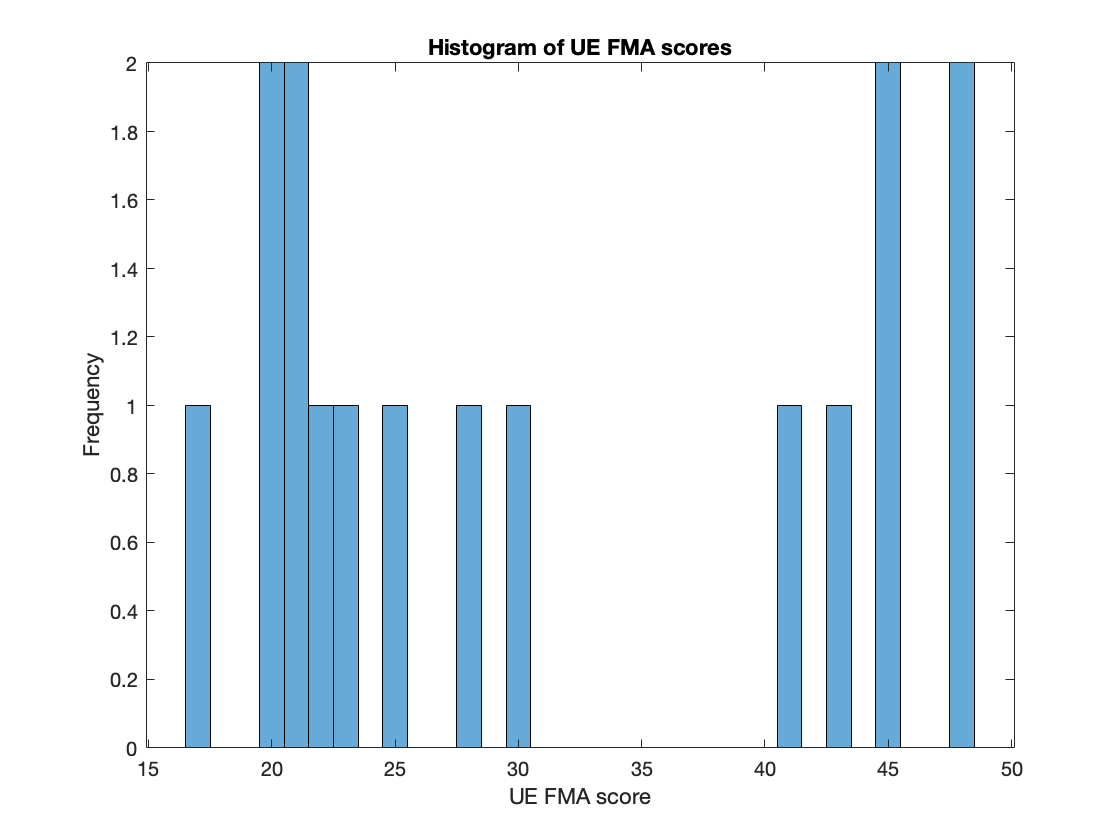

clear; clc;

% import data 
UE_FMA = [21;20;20;17;25;30;48;41;45;45;43;28;48;21;23;22];

% plot to visualize distribution 
figure;
histogram(UE_FMA)
xlabel('UE FMA score')
ylabel('Frequency')
title('Histogram of UE FMA scores')

function [ref_dur, test_dur, done, right] = stepping(response)

% INPUT:
% response: which arm moved faster? (1 = right; 2 = left)

% IC's
% Preset movement times
mts1 = [5 5 3.409 2.5 1.973 NaN 1.874;
   1.0130000000000001 1.1360000000000001 1.293 1.5 1.7850000000000001 NaN ...
   1.874];

mts2 = [1.6300000000000001 1.3880000000000001 1.209 1.071 0.961 NaN 0.937;
   0.657 0.707 0.765 0.833 0.914 NaN 0.937];

mts3 = [0.872 0.797 0.735 0.681 0.635 NaN 0.624;
   0.487 0.513 0.543 0.57600000000000007 0.614 NaN 0.624];

mts4 = [0.595 0.559 0.528 0.5 0.47400000000000003 NaN 0.468;
   0.386 0.403 0.421 0.441 0.462 NaN 0.468];

mts5 = [0.451 0.431 0.41200000000000003 0.394 0.378 NaN 0.374;
   0.32 0.331 0.34400000000000003 0.357 0.371 NaN 0.374];

mts6 = [0.364 0.35000000000000003 0.337 0.326 0.315 NaN 0.312; 
    0.273 0.281 0.29 0.3 0.309 NaN 0.312];

poss = 1:length(mts1)-2; % possible index values

% Set persistent variables (remembered by function each time it is called) 
persistent n refsp testsp sp correct wrong
if isempty(n) || isempty(refsp) || isempty(testsp) || isempty(correct) || ...
        isempty(wrong) 
    % starting values 
    refsp = poss(end); % right arm duration 
    testsp = poss(1); % left arm duration 
    n = poss(end); % space between values in speed vector 
    sp = randi(6,1); % current mt vector 
    correct = 0; % # of correct answers 
    wrong = 0; % # of wrong answers
end


% once they get 60 (total) correct answers done
done = 0;
if correct == 60 
        %sprintf('End of experiment')
        ref_dur = 10;
        test_dur = 10;
        done = 1; % done? 1 = yes, 0 = no
        right = nan;
        return
end

% Set mt vector 
if sp == 1
    mt = mts1;
elseif sp == 2
    mt = mts2;
elseif sp == 3 
    mt = mts3;
elseif sp == 4
    mt = mts4;
elseif sp == 5 
    mt = mts5;
elseif sp == 6
    mt = mts6;
else 
    mt = [10 10 10 10 10 NaN 10; 
    10 10 10 10 10 NaN 10];
end

if response == 1 && (refsp < testsp) || response == 2 && (testsp < refsp) 
    % if answered correctly    
    
    n = n-1; % make speeds closer together by 1 "step" 
    if n < 1 % repeat smallest gap until wrong 
        n = 1;
    end
    correct = correct + 1; % add to the correct variable 
    
    right = 1; % for analysis
else % if answered wrong
   
    n = n+1; % make speeds further apart by 1 "step" 
    if n > 5 % repeat largest gap until correct 
        n = 5;
    end
    wrong = wrong+1; % add to the wrong variable 
    
    right = 0; % for analysis
end

% Randomly choose speed index
ref_dur = mt(1,end);
col = length(mt) - (n+1);

rnd = rand();
if rnd > 0.5
    test_dur = mt(2,col);
elseif rnd < 0.5 
    test_dur = mt(1,col);
else 
    test_dur = mt(1,col);
end

% for testing 
sprintf('Correct: %d; Wrong: %d; n: %d; test_dur: %d, ref_dur: %d',...
   correct, wrong, n, test_dur, ref_dur)

% Reset persistent variables
refsp = ref_dur;
testsp = test_dur;
sp = randi(6,1); % randomly select next distribution 

% OUTPUT:
% right_dur & left_dur: right and left arm movement duration, respectively

end
